# MSM semestrální práce

Jakub Znamenáček

## Inicializace

clc
close all %zavře všechna okna
clearvars %smaže proměnné z workspace

## zadání

m1 = 5; %kg
m2 = 2; %kg
a = 0.5; %m
b = 0.75; %m
c = 1.25; %m
d = 1; %m
k = 5.8*100; %N/m
kt = 1.1*100; %Nm/rad
b1 = 6.1; %Ns
b2 = 8.8; %Ns
g = 9.81; %m/s2

phi10 = deg2rad(35); %rad
dphi10 = 0; %rad/s
phi20 = 0; %rad
dphi20 = 0; %rad/s

M_t = 0; %Nm

#### dopočtené hodnoty

G1 = m1*g; %kgm/s2°
G2 = m2*g; %kgm/s2
I1 = m1*b^2; %kg*m2
I2 = m2*c^2; %kg*m2

x10 = phi10; %rad
x20 = dphi10; %rad/s
x30 = phi20; %rad
x40 = dphi20; %rad/s
x0 = [x10,x20,x30,x40];

## nelineární model

#### stavový popis

stavové proměné jsou: $x_1 =\varphi_1$, $x_2 =\dot{ \varphi}_1$, $x_3 = \varphi_2$, $x_4 = \dot{\varphi}_2$


$$\dot x_1=x_2$$



$$\dot x_2 =\frac {-x_1k_t - b_1x_2-k\left(d-\sqrt{(d-a(\sin(x_1)-\sin(x_3))^2+(a(\cos(x_3)-\cos(x_1)))^2}\right)\cos(\arctan\left(\frac{a\left(\cos(x_3)-\cos(x_1)\right)}{d-a\left(\sin(x_1)-\sin(x_3)\right)}\right)a\cos(x_1)+G_1b\sin(x_1)-M_t} {I_1}$$



$$\dot x_3 =x_4$$



$$\dot x_4 = \frac {-b_2x_4+k\left(d-\sqrt{(d-a(\sin(x_1)-\sin(x_3))^2+(a(\cos(x_3)-\cos(x_1)))^2}\right)\cos(\arctan\left(\frac{a\left(\cos(x_3)-\cos(x_1)\right)}{d-a\left(\sin(x_1)-\sin(x_3)\right)}\right)a\cos(x_3)+G_2c\sin(x_3)}{I_2}$$


#### nastavení simulace

tmax=5;%s - maximální čas simulace


#### výpočet pomocí simuliku

simulinkTempNelinearni = sim('NELINEARIZOVANEsimulink.slx',tmax);
phi1 = simulinkTempNelinearni.x1;
phi2 = simulinkTempNelinearni.x3;
Fp_simulink = simulinkTempNelinearni.Fp;

#### graf závislosti phi1 a phi2 na čase

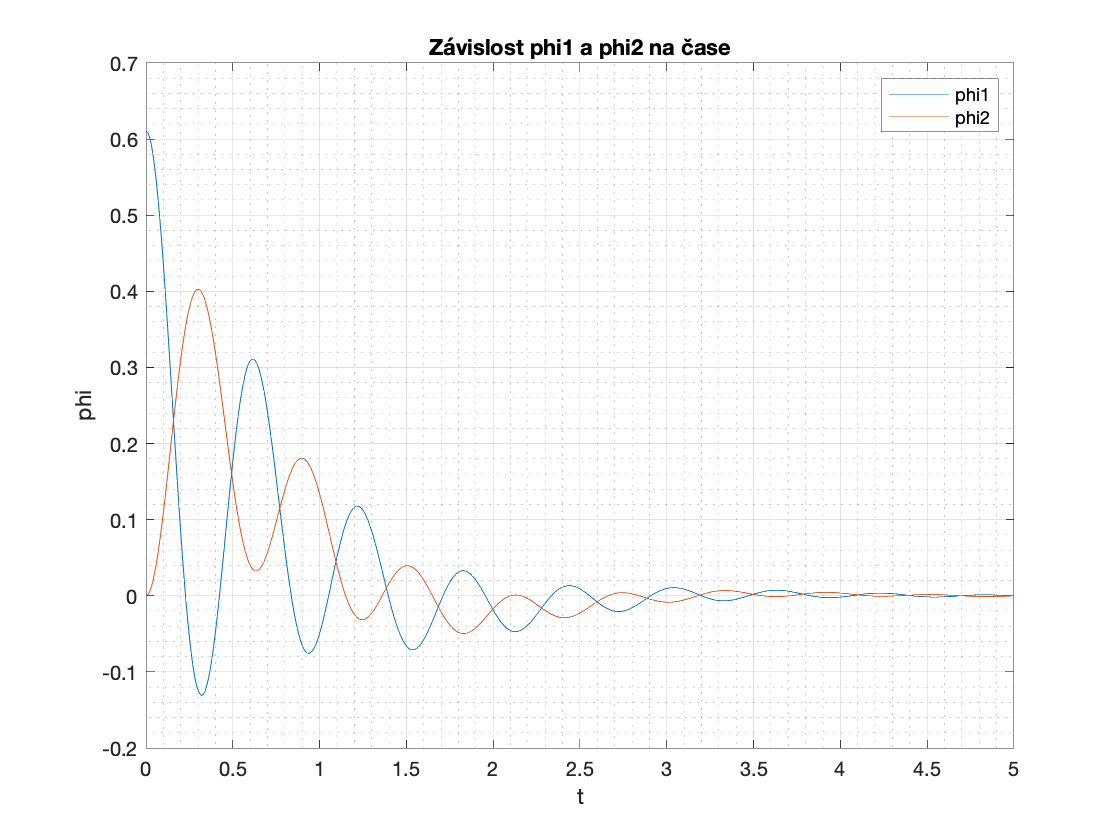

figure
plot(phi1)
hold on %podrží graf na obrazovce, aby mohl být přidán další
plot(phi2)
grid on %zapne mřížku grafu
grid minor %zapne přesnější mřížku
title('Závislost phi1 a phi2 na čase') %nadpis grafu
xlabel('t') %popis osy x
ylabel('phi') %popis osy y
legend({'phi1','phi2'},'Location','northeast') %legenda grafu

#### animace

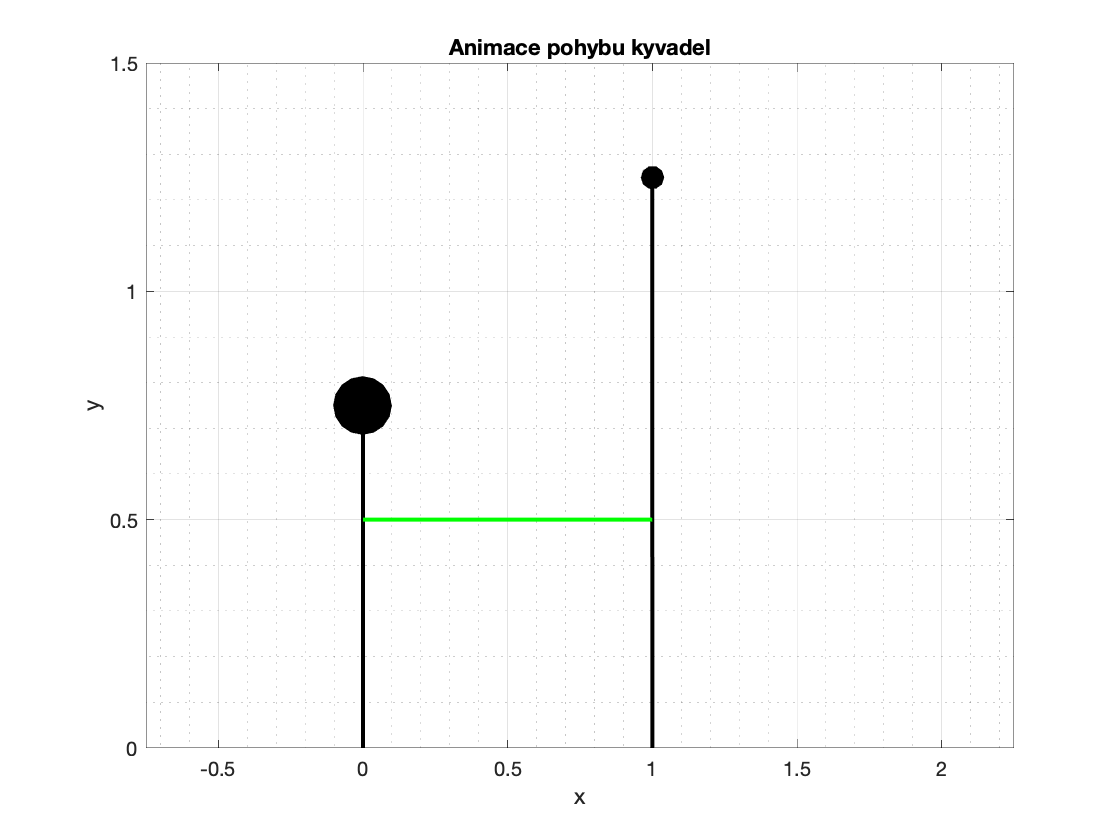


%close all
figure
%plot(0,0)
%grid on

for i = 1:length(phi1.Data)
    cla
    
    %kyvadlo 1
    plot([0 b*sin(phi1.Data(i))],[0 b*cos(phi1.Data(i))],'LineWidth',2,"Color",[0 0 0]) %kyvadlo 1 tyč
    hold on
    plot(b*sin(phi1.Data(i)),b*cos(phi1.Data(i)),'MarkerSize',m1*20,'Marker','.','LineWidth',2,"Color",[0 0 0]); %kyvadlo 1 závaží
    
    %kyvadlo 2 
    hold on
    plot(d+[0 c*sin(phi2.Data(i))],[0 c*cos(phi2.Data(i))],'LineWidth',2,"Color",[0 0 0]) %kyvadlo 2 tyč
    hold on
    plot(d+c*sin(phi2.Data(i)),c*cos(phi2.Data(i)),'MarkerSize',m2*20,'Marker','.','LineWidth',2,"Color",[0 0 0]); %kyvadlo 2 závaží
    
    %pružina
    hold on
    if(Fp_simulink.Data(i)>0)
        plot([a*sin(phi1.Data(i)) (d+a*sin(phi2.Data(i)))],[a*cos(phi1.Data(i)) a*cos(phi2.Data(i))],'LineWidth',2,"Color",[1 0 0]) % kyvadlo 1 tyč
    else
        plot([a*sin(phi1.Data(i)) (d+a*sin(phi2.Data(i)))],[a*cos(phi1.Data(i)) a*cos(phi2.Data(i))],'LineWidth',2,"Color",[0 1 0]) % kyvadlo 1 tyč
    end
    
    
    %nastavení rozsahů os
    xlim([-b (d+c)])
    ylim([0 c*1.2])
    
    
    
    %popis grafu
    title('Animace pohybu kyvadel') %nadpis grafu
    xlabel('x') %popis osy x
    ylabel('y') %popis osy y
    grid on %zapne mřížku grafu
    grid minor %zapne přesnější mřížku
    
    %nastavení rychlosti animace
    pause(.0001)
end

## Lineární model

### Linearizace

%definice symbolických proměnných
syms x1;
syms x2;
syms x3;
syms x4;

syms Mt; %Nm

%odkomentovat pro kontrolu rovnic
%{
syms a; %m
syms b; %m
syms c; %m
syms d; %m
syms k; %N/m
syms kt; %Nm/rad
syms b1; %Ns
syms b2; %Ns
syms g; %m/s2
syms G1; %kgm/s2°
syms G2; %kgm/s2
syms I1; %kg*m2
syms I2; %kg*m2
%}

#### stavový popis

stavové proměné jsou: $x_1 =\varphi_1$, $x_2 =\dot{ \varphi}_1$, $x_3 = \varphi_2$, $x_4 = \dot{\varphi}_2$

pomocné výpočty


$$\delta x = d-a\left(sin(x_1)-sin(x_3)\right)$$



$$\delta y = a\left( cos(x_3)-cos(x_1)\right)$$



$$\Delta l = d-\sqrt{\delta x^2+\delta y^2}$$



$$F_p =k\Delta l$$



$$\varphi_p = \arctan\left(\frac{\delta y}{\delta x}\right)$$


%pomocné výpočty
deltax = d-a*(sin(x1)-sin(x3));
deltay = a*(cos(x3)-cos(x1));
DELTAl = d-sqrt(deltax^2+deltay^2);
Fp =k*DELTAl;
phip = atan(deltay/deltax);

stavové rovnice


$$\dot x_1=f_1=x_2$$



$$\dot x_2 =f_2=\frac {-x_1k_t - b_1x_2-k\left(d-\sqrt{(d-a(\sin(x_1)-\sin(x_3))^2+(a(\cos(x_3)-\cos(x_1)))^2}\right)\cos(\arctan\left(\frac{a\left(\cos(x_3)-\cos(x_1)\right)}{d-a\left(\sin(x_1)-\sin(x_3)\right)}\right)a\cos(x_1)+G_1b\sin(x_1)-M_t} {I_1}$$



$$\dot x_3=f_3 =x_4$$



$$\dot x_4 =f_4= \frac {-b_2x_4+k\left(d-\sqrt{(d-a(\sin(x_1)-\sin(x_3))^2+(a(\cos(x_3)-\cos(x_1)))^2}\right)\cos(\arctan\left(\frac{a\left(\cos(x_3)-\cos(x_1)\right)}{d-a\left(\sin(x_1)-\sin(x_3)\right)}\right)a\cos(x_3)+G_2c\sin(x_3)}{I_2}$$


%stavové rovnice
f1 = x2;
f2 =(-x1*kt -b1*x2-Fp*cos(phip)*a*cos(x1)+G1*b*sin(x1)-Mt)/I1;
f3 =x4;
f4 =(-b2*x4 +Fp*cos(phip)*a*cos(x3)+G2*c*sin(x3))/I2;

#### singulární body

ověření, že bod $\textbf{x}_s=\left[ \begin{array}{rrr}0 \\ 0 \\0 \\0\\ \end{array}\right]$splňuje rovnici $\textbf{f}=0$

subs(f1, [x1, x2, x3, x4], [0, 0, 0, 0])

$$ans = 0$$

subs(f2, [x1, x2, x3, x4], [0, 0, 0, 0]) %Ještě nastavit Mt jako 0 !!!

$$ans = -\frac{16\,\mathrm{Mt}}{45}$$

subs(f3, [x1, x2, x3, x4], [0, 0, 0, 0])

$$ans = 0$$

subs(f4, [x1, x2, x3, x4], [0, 0, 0, 0])

$$ans = 0$$

linearizace v singulárním bodě stavového prostoru $\textbf{x}_s=\left[ \begin{array}{rrr}0 \\ 0 \\0 \\0\\ \end{array}\right]$


$$\textbf{f} = DOPLNIT$$


vzhledem k tomu, že $\textbf{x}_s$ je rovno nule, 

xs = [0 0 0 0]; %singulární bod
Mts = 0;
x = [x1 x2 x3 x4]; %vektor stavových proměnných

#### Linearizované stavové rovnice

%linearizované stavové rovnice
f1_lin = subs(diff(f1,x1), x, xs)*x1 + subs(diff(f1,x2), x, xs)*x2 ...
       + subs(diff(f1,x3), x, xs)*x3 + subs(diff(f1,x4), x, xs)*x4 + subs(diff(f1,Mt), Mt, Mts)*Mt

$$f1\_lin = x_{2}$$

f2_lin = subs(diff(f2,x1), x, xs)*x1 + subs(diff(f2,x2), x, xs)*x2 ...
       + subs(diff(f2,x3), x, xs)*x3 + subs(diff(f2,x4), x, xs)*x4 + subs(diff(f2,Mt), Mt, Mts)*Mt

$$f2\_lin = \frac{464\,x_{3}}{9}-\frac{5819\,x_{1}}{75}-\frac{488\,x_{2}}{225}-\frac{16\,\mathrm{Mt}}{45}$$

f3_lin = subs(diff(f3,x1), x, xs)*x1 + subs(diff(f3,x2), x, xs)*x2 ...
       + subs(diff(f3,x3), x, xs)*x3 + subs(diff(f3,x4), x, xs)*x4 + subs(diff(f3,Mt), Mt, Mts)*Mt

$$f3\_lin = x_{4}$$

f4_lin = subs(diff(f4,x1), x, xs)*x1 + subs(diff(f4,x2), x, xs)*x2 ...
       + subs(diff(f4,x3), x, xs)*x3 + subs(diff(f4,x4), x, xs)*x4 + subs(diff(f4,Mt), Mt, Mts)*Mt

$$f4\_lin = \frac{232\,x_{1}}{5}-\frac{4819\,x_{3}}{125}-\frac{352\,x_{4}}{125}$$

#### Maticový zápis

$\dot x= Ax + Bu$, $y = Cx+Du$

A = [subs(diff(f1,x1), x, xs) subs(diff(f1,x2), x, xs) subs(diff(f1,x3), x, xs) subs(diff(f1,x4), x, xs);
     subs(diff(f2,x1), x, xs) subs(diff(f2,x2), x, xs) subs(diff(f2,x3), x, xs) subs(diff(f2,x4), x, xs);
     subs(diff(f3,x1), x, xs) subs(diff(f3,x2), x, xs) subs(diff(f3,x3), x, xs) subs(diff(f3,x4), x, xs);
     subs(diff(f4,x1), x, xs) subs(diff(f4,x2), x, xs) subs(diff(f4,x3), x, xs) subs(diff(f4,x4), x, xs)]

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{5819}{75} & -\frac{488}{225} & \frac{464}{9} & 0\\ 0 & 0 & 0 & 1\\ \frac{232}{5} & 0 & -\frac{4819}{125} & -\frac{352}{125} \end{array}\right)$$

B = [subs(diff(f1,Mt), Mt, Mts);
     subs(diff(f2,Mt), Mt, Mts);
     subs(diff(f3,Mt), Mt, Mts);
     subs(diff(f4,Mt), Mt, Mts)]

$$B = \left(\begin{array}{c} 0\\ -\frac{16}{45}\\ 0\\ 0 \end{array}\right)$$

C = [1 0 0 0; 0 0 1 sym(0)] %%sym(0) jen aby matlab matici vypsal hezky v live scriptu

$$C = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)$$

 D = [0 ;sym(0)]

$$D = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

 A = double(A);
 B = double(B);
 C = double(C);
 D = double(D);

 

#### nastavení simulace

tmax=5;%s - maximální čas simulace


#### výpočet pomocí simuliku

simulinkTemp = sim('LINEARIZOVANEsimulink.slx',tmax);
phi1_lin = simulinkTemp.x1;
phi2_lin = simulinkTemp.x3;

#### graf závislosti phi1 a phi2 na čase

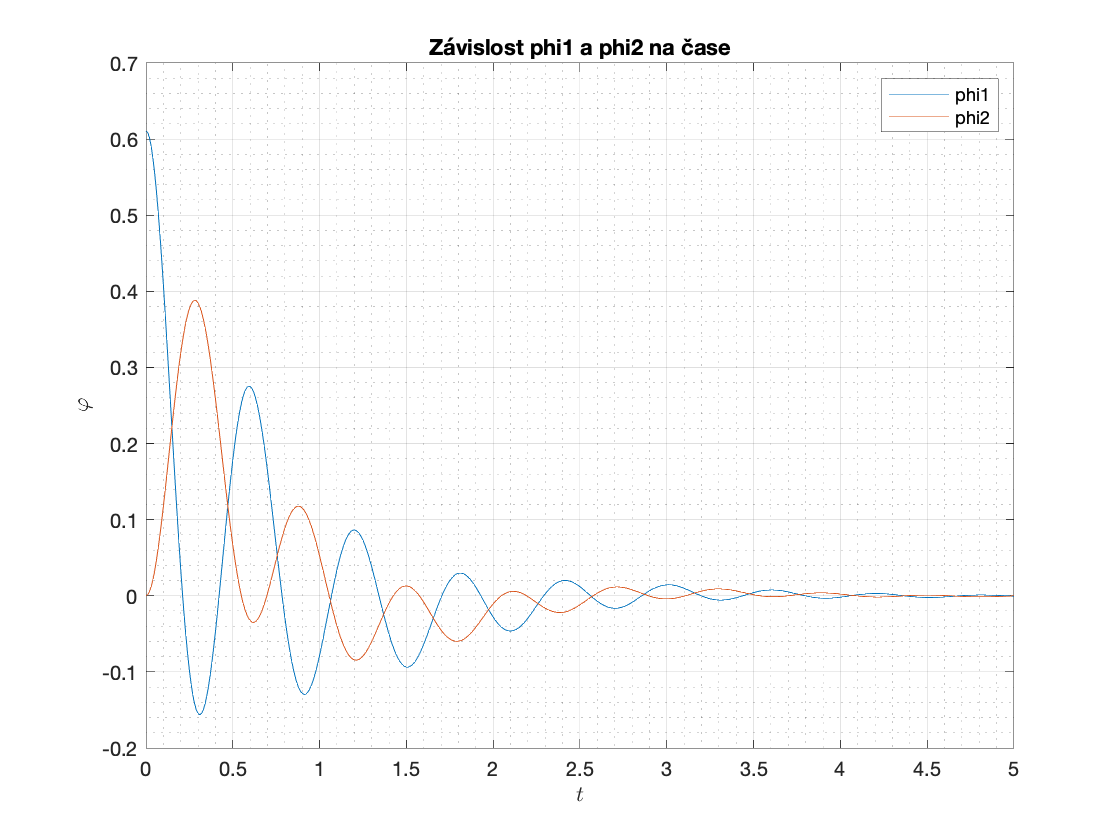

figure
plot(phi1_lin)
hold on %podrží graf na obrazovce, aby mohl být přidán další
plot(phi2_lin)
grid on %zapne mřížku grafu
grid minor %zapne přesnější mřížku
title('Závislost phi1 a phi2 na čase') %nadpis grafu
xlabel('$t$','Interpreter','latex') %popis osy x
ylabel('$\varphi$','Interpreter','latex') %popis osy y
legend({'phi1','phi2'},'Location','northeast') %legenda grafu

#### animace

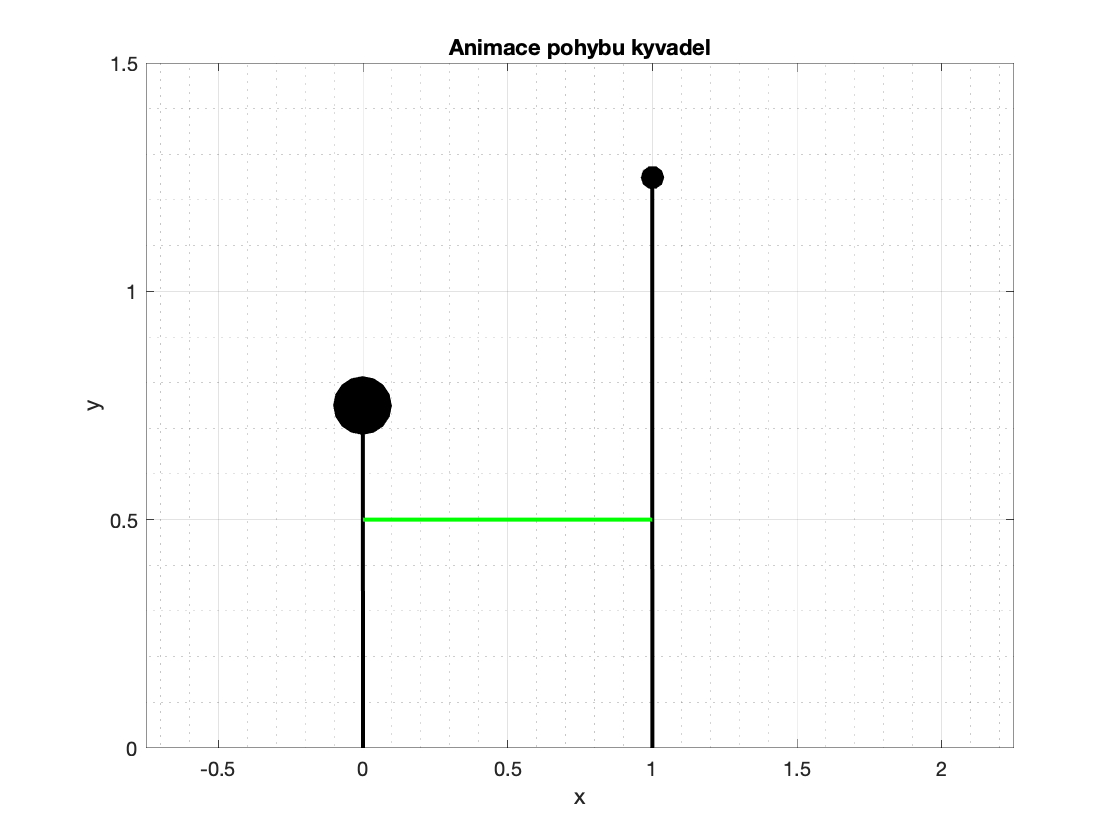


%close all
figure
%plot(0,0)
%grid on

for i = 1:length(phi1_lin.Data)
    cla
    
    %kyvadlo 1
    plot([0 b*sin(phi1_lin.Data(i))],[0 b*cos(phi1_lin.Data(i))],'LineWidth',2,"Color",[0 0 0]) %kyvadlo 1 tyč
    hold on
    plot(b*sin(phi1_lin.Data(i)),b*cos(phi1_lin.Data(i)),'MarkerSize',m1*20,'Marker','.','LineWidth',2,"Color",[0 0 0]); %kyvadlo 1 závaží
    
    %kyvadlo 2 
    hold on
    plot(d+[0 c*sin(phi2_lin.Data(i))],[0 c*cos(phi2_lin.Data(i))],'LineWidth',2,"Color",[0 0 0]) %kyvadlo 2 tyč
    hold on
    plot(d+c*sin(phi2_lin.Data(i)),c*cos(phi2_lin.Data(i)),'MarkerSize',m2*20,'Marker','.','LineWidth',2,"Color",[0 0 0]); %kyvadlo 2 závaží
    
    %pružina
    hold on
    if(phi1_lin.Data(i)>phi2_lin.Data(i)) %NUTNO ZKONTROLOVAT
        plot([a*sin(phi1_lin.Data(i)) (d+a*sin(phi2_lin.Data(i)))],[a*cos(phi1_lin.Data(i)) a*cos(phi2_lin.Data(i))],'LineWidth',2,"Color",[1 0 0]) % kyvadlo 1 tyč
    else
        plot([a*sin(phi1_lin.Data(i)) (d+a*sin(phi2_lin.Data(i)))],[a*cos(phi1_lin.Data(i)) a*cos(phi2_lin.Data(i))],'LineWidth',2,"Color",[0 1 0]) % kyvadlo 1 tyč
    end
    
    
    %nastavení rozsahů os
    xlim([-b (d+c)])
    ylim([0 c*1.2])
    
    
    
    %popis grafu
    title('Animace pohybu kyvadel') %nadpis grafu
    xlabel('x') %popis osy x
    ylabel('y') %popis osy y
    grid on %zapne mřížku grafu
    grid minor %zapne přesnější mřížku
    
    %nastavení rychlosti animace
    pause(.0001)
end

#### graf rozdílu mezi linearizovaným a nelinearizovaným modelem

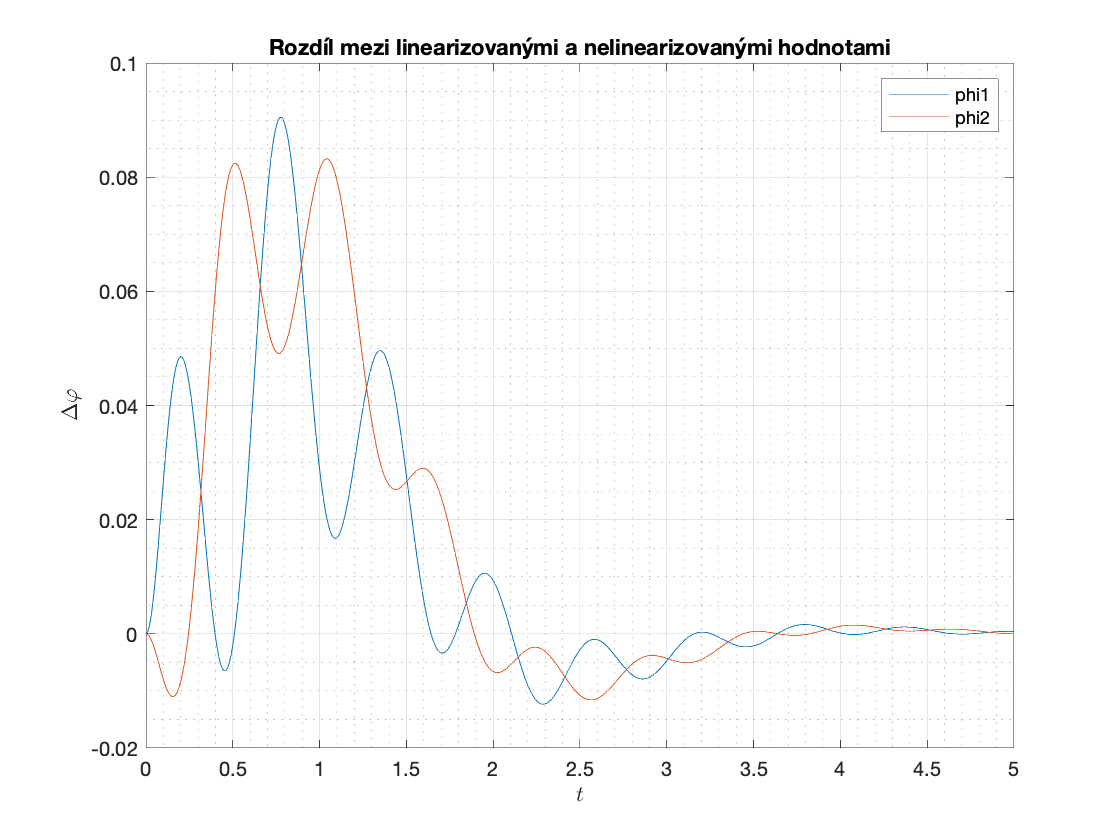

if (length(phi1.Data)==length(phi1_lin.Data)) %% zkontroluje, že data mají stejnou velikost
    figure
    plot(phi1-phi1_lin)
    hold on %podrží graf na obrazovce, aby mohl být přidán další
    plot(phi2-phi2_lin)
    grid on %zapne mřížku grafu
    grid minor %zapne přesnější mřížku
    title('Rozdíl mezi linearizovanými a nelinearizovanými hodnotami') %nadpis grafu
    xlabel('$t$','Interpreter','latex') %popis osy x
    ylabel('$\Delta\varphi$','Interpreter','latex') %popis osy y
    legend({'phi1','phi2'},'Location','northeast') %legenda grafu 
end